# Stock Picker Project

## Introduction

We will create our own stock picker program by modifying the bottom-level functions in this Live Script. The Live Script reads the stock data from Yahoo and passes it to the `MakeMoney()` function.  

The MakeMoney() function returns a transaction table and we write the transaction table to a CSV file so we can compare results and find a winning player.

## Calling MakeMoney()

MakeMoney() takes a struct array of stock data and creates a file of stock transactions.  Optionally, it returns graphs that show which stock decisions the script made for each stock.

You can modify MakeMoney(), but it's unlikely you'd want to do that.

% Only load the priceHistory if it doesn't already exist in our workspace.
if ~exist("priceHistory", 'var')
    priceHistory = hist_stock_data('01012024',now,'TestStocks.txt');
end
if ~exist('graphs','var')
[tt, graphs] = MakeMoney(priceHistory,true);
else
    tt = MakeMoney(priceHistory,false);
end

Write the transaction table to a CSV vile with your initials in it:

% Write the table to a file.
writetable(tt,'RStransactions.csv');

## Processing the Transactions

We call the `processTransactions()` function for two reasons:

- We want to be sure that our transaction table is valid.

- We want to know how well our algorithm did.

processTransactions() returns a table that shows how well our stock transactions did.  We start with $10,000, which tells us whether the number below is a good or bad result.

% process the transactions and find out how much money the MakeMoney()
% function made. 
format short g
processTransactions("players.csv",priceHistory,"RStransactions.csv")

ans = 1x2 table
          players           CashValue
    ____________________    _________

    rsalemi@natickps.org     9995.3  


## Documenting all 

## Using MACD to make money

In this project, you can use whatever technical stock algorithm you like.  Technical investing is a deep rabbit hole. The `MakeMoney() `function uses a set of exponential moving averages to decide whether to buy or sell a stock.

### Exponential Moving Averages (EMA)

A *Simple Moving Average* (SMA) sums data over a time period and divides by the number of days in the time period. It does this each day with a moving window of numbers.

While the SMA weighs all days in a time period equally, the *Exponential Moving Average* (EMA) weighs the recent data more heavily than past data. It does this by combining todays EMA number with the previous day's EMA number. Thus old values eventually fade away and have no influence. 

I've given you the `calcEMA()` function in the `calcEMA.m` file so you don't have to calculate EMAs in your program directly.  You can use the function.  The `calcEMA()` function  calculates the EMA for all rows in an array, so you can process all stock prices in one function call. 

function ema = calcEMA(prices, N)
    % calculateEMA calculates the Exponential Moving Average for 
    % multiple stocks over N days. 
    %
    % Arguments:
    % prices - An array of prices, one row per stock.
    % N - The number of days for the EMA calculation.
    %
    % Returns:
    % ema - A vector containing the EMA of the given prices.



    % Ensure N is a positive integer
    if ~isscalar(N) || N < 1 || N ~= round(N)
        error('N must be a positive integer scalar');
    end

    % Initialize the EMA vector
    ema = zeros(size(prices));

    % Smoothing factor k
    k = 2 / (N + 1);

    % Start the EMA with the first price point
    ema(:,1) = prices(:,1);

    % Calculate the EMA for each price point
    for ii = 2:width(prices)
        ema(:,ii) = (prices(:,ii) .* k) + (ema(:,ii-1) .* (1 - k));
    end
end

### MACD Analysis

`MakeMoney()` uses multiple EMAs to find buying signals.  Moving average Convergence/Divergence (MACD) tells us when a long term EMA and a short term EMA are getting close to each other or are diverging.  We calculate MACD like this.


$$\textrm{MCAD}=12\textrm{Day}\;\textrm{EMA}\left(\textrm{AdjCloses}\right)-26\textrm{DayEMA}\left(\textrm{AdjCloses}\right)$$


The first thing to note is that the MACD is negative if the 12Day EMA drops below the 26Day EMA.  Having a short term EMA fall below a longer term EMA is usually a bad sign for a stock. Conversely, having the short term EMA rise above the longer term EMA is a good sign. It shows that the stock is popular and beating its previous performance.

#### The `signal` line and the histogram

However, the MACD can be finicky, bouncing up and down from day to day.  To solve htis problem we smooth the MACD with a 9 day EMA called the signal line.


$$\textrm{signal}=9\textrm{DayEMA}\left(\textrm{MCAD}\right)$$


Now we have a way of checking to see whether changes to the MACD have long term staying power.  We can now use the difference between the MACD and its signal line to create a buying and selling signal called *the histogram.  *If MACD is above its signal we have a positive histogram, if it is below the signal we have a negative histogram.


$$\textrm{histogram}=\textrm{MCAD}-\textrm{signal}$$


### Analyzing Stocks using MACD

Now we can look at the graph we created above to analyze our stock tool.

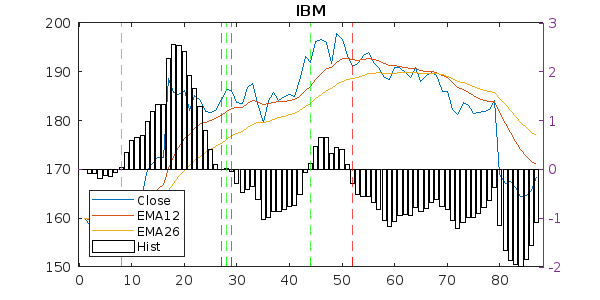

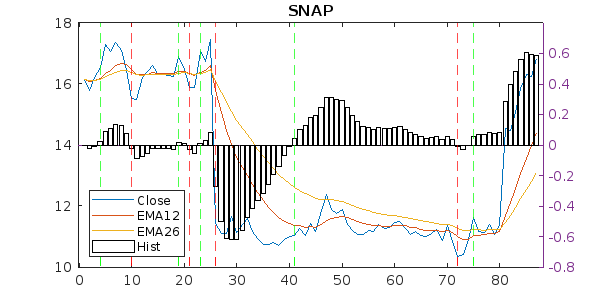

fig = figure(graphs(string({priceHistory.Ticker})=='IBM'));
set(fig,'Position',[300,100,600,300]);

Looking at the graph above we see the following information:

- Close—This is the daily closing price for IBM in 2024

- EMA12—This is the 12-day exponential moving average for IBM

- EMA26—This is the 26-day exponential moving average for IBM

- Hist—The graph does not show the MACD line or its signal. Instead it shows the difference between them using the histogram.

My algorithm buys a stock whenever the histogram goes from negative to positive, and sells the stock as soon as the histogram goes from positive to negative.  It does not look at the size of the swings, it only sees the trasitions between positive and negative and back.

The graph above uses green vertical lines to highlight buying signals and red vertical lines to highlight selling signals. The algorithm did okay with IBM.  It bought low on day 8, sold higher on day 28.  Then it did a little buy and sell maneuver that made no difference.  Finally it bought on day 43 and sold on day 53, losing money.  

Let' see how we did with Snapchat.

snapFig = figure(graphs(string({priceHistory.Ticker})=='SNAP'));
set(snapFig,'Position',[300,100,600,300]);

Here we see that the algorithm thrashes a bit, but clearly notices a buy sign on day 41 when SNAP tries to recover.  Sadly, the recovery fails and we sell SNAP at a low point, though we do buy it back as soon as it starts to rise again.  In the rest of this Live Sheet, we'll look at the MakeMoney`()` function to understand how it works.

## Function:  MakeMoney`(priceHistory)`

`MakeMoney()` does three things:

- Extracts data from the stock struct array using the `extractData()` function.

- Finds the buy and sell dates using the `findTransactionDates() `function.

- Creates and returns a transaction table using the `createTransactionTable()` function.

You modify these three functions to create your own stock processing tool.  You can choose to modify one, or all of the functions.  You'll only need to modify `extractData()` if your algorithm uses data beyond adjusted stock closes..

% The MakeMoney() function
% MakeMoney() takes the structural array returned by hist_stock_data()
% and creates a table of transactions that are supposed implement a
% profitable technical stock investment strategy.
%
% MakeMoney() returns the table of transactions and an array of graphs for
% each stock if the second argument is set to true.  If you call
% MakeMoney() with one argument, you get an empty matrix for the graphs.
function [transTable, graphs] = MakeMoney(priceHistory, makeGraph) 
% the special 'varargin' (variable arguments input) returns a cell array of
% optional argument values.

% Check the number of arguments.  If it is greater than 1 then check the
% first varible argument to see if the user requested graphs.  Without the
% second argument, we do not create the graph (they take time.)

    [tickers, dates, stockCloses] = extractData(priceHistory);
    [buyDates, sellDates, graphs] = findTransactionDates(tickers, stockCloses, makeGraph);
    transTable = createTransactionTable(dates, tickers, buyDates, sellDates);

end

## Function: `ExtractData(priceHistory)`

This function extracts the data from the `hist_stock_data() `struct array.  It returns a list of ticker symbols, the dates 

First, we create a table from the struct array. This makes it easier to extract some information.

function [tickers, dates, stockCloses] = extractData(priceHistory)
    % Convert the struct arrray to a table
    stockTable = struct2table(priceHistory); 

stockTable stores the ticker symbols in an array of cell arrays that contain character arrays.  This is difficult to work with.  We get the `stockTable.Ticker` array and covert it to strings and then a categorical array.  This makes our program faster and it takes less memory.

    % The ticker symbols are categorical because we reuse them a lot.
    tickers = categorical(string(stockTable.Ticker));


We make an array of all the stocks and all the dates of their transactions.  These dates are likely the same for all stocks, but capturing all the dates ensures that we have the correct data for each stock.

The stockTable.Date variable contains an array of cell arrays.  We extract all the arrays using the {} operator and concatenate them together to create a large array of dates with the size `stocks x dates.` We store the stocks in rows and the dates in columns.

    dates = [stockTable.Date{:,:}]';
    numStocks = numel(tickers);
    numDates = width(dates);

Now it is time to make a large array that contains all the adjusted closing prices for all the stocks on each day.  The array size is `numStocks` rows by `numDates` columns.  Each cell in the AdjClose array contains a cell array of stock prices.  We loop through all the stocks and then fill the `stockCloses` row with the data in the `AdjClose` array.  We transpose the array to fit the `stockCloses` row.

    stockCloses = zeros(numStocks,numDates);
    for ii = 1:numStocks
        stockCloses(ii,:) = stockTable{ii,"AdjClose"}{1,1}';
    end
end

## Function: `findTransactionDates(tickers, dates, stockCloses)`

Now, we have an array with one row for each stock, and adjusted closing prices for each day.  Now we're ready to calculate the Exponential Moving Average (EMA) for every stock at the same time. 

function [buyDates, sellDates, graphs] = findTransactionDates(tickers, stockCloses, makeGraphs)
    numStocks = numel(tickers);
    shortEMA = calcEMA(stockCloses,12);
    longEMA = calcEMA(stockCloses,26);

`shortEMA` and `longEMA` arrays contain a row for every stock, and columns for all the dates, but they contain moving averages instead of stock prices.

Now we calculate the Moving Average Convergence Divergence (MACD).  We subtract the 26 day EMA from the 12 day EMA to get the MACD. This is our first stock signal.

    MACD = shortEMA - longEMA;

The MACD is too noisy to make stock decisions, so we're going to take the 9 day Expontential Moving Average of the MACD to get a comparison signal that we'll name `signal`.

    signal = calcEMA(MACD,9);

Now that we have the MACD and the signal. we subtract them to get the histogram.

    MACDHistograms = MACD - signal;

### Buying signals and selling signals

Now that we have the MACD histograms for all the stocks, we can choose our buying signals and selling signals.  This is the most arbitrary part of the process.  My algorithm is very simple, but that's probably why it doesn't make a lot of money. 

More advanced algorithms take into account the volume of stocks sold on a day, the long term trends of the histogram, and recent highs and lows.  My algorithm simply buys a stock if its histogram goes up from negative to positive and sells it if the histogram goes down from positive to negative. We find this information across all histograms for all stocks.

First we create empty arrays of buy signals and sell signals. 

    buySignals = false(numStocks,width(MACDHistograms));
    sellSignals = false(numStocks,width(MACDHistograms));


Now we create arrays for all negative histogram values and all positive histogram values.

    MACDNeg = MACDHistograms < 0;
    MACDPos = MACDHistograms > 0;


We line up one histogram with the other histogram offset buy a day.  We buy when the early histogram is negative and the next day histogram is positive.  We sell when the early histogram is postive and the next day histogram is negative.

    buySignals(:,2:end) = MACDNeg(:,1:end-1) & MACDPos(:, 2:end);
    sellSignals(:,2:end) = MACDPos(:,1:end-1) & MACDNeg(:, 2:end);


We now have two logical arrays, `buySignals` contains 1's corresponding to the days to buy a stock and `sellSignals` contains  1's on the days to sell a stock.   We use these with the f`ind() `function to get the indices of the dates to buy and sell stocks.

`buys` contains the index of the days we buy each stock, and `sells` contains the index of the days that we sell each stock.

    buyDates = cell(1,numStocks);
    sellDates = cell(1,numStocks);
    for ii = 1:numStocks
            buyDates{ii} = find(buySignals(ii,:));
            sellDates{ii} = find(sellSignals(ii,:));
    end

### Make the graphs

If the user wants graphs of all the stocks, we create them here.  We return an array of figure objects containing each graph.

    if makeGraphs==true
        graphs = zeros(1, numStocks);


Loop through all the stocks and create a graph for each without displaying it on the screen.


        for ss = 1:numStocks
            graphs(ss) = figure('Visible','off');
            plot(stockCloses(ss,:));
            title(tickers(ss));
            hold on;
            plot(shortEMA(ss,:));
            plot(longEMA(ss,:));


The histogram has numbers centered around zero, so we use the right axis instead of the left so that we can see the histogram on the same graph as the stock prices.

            yyaxis right;
            bar(MACDHistograms(ss,:),'FaceAlpha', 0.0);


Create vertical lines at each buy and sell. 

            for cc = 1:width(buySignals)
               if buySignals(ss,cc) == 1
                   xline(cc, '--g', 'LineWidth', 1);
               end
               if sellSignals(ss,cc) == 1
                   xline(cc, '--r', 'LineWidth', 1);
               end
    
            end
            legend('Close', 'EMA12','EMA26','Hist','Location','southwest');
            hold off
        end
    else
        graphs = [];
    end

end

## Function: `createTransactionTable(buyDates, sellDates)`

Now we're going to create our transaction table.  First we define an empty table that contains the correct varibles. 

function transTable = createTransactionTable(dates, tickers, buyDates, sellDates)
    transTable = table('Size', [0 5], 'VariableTypes',{'datetime','categorical','categorical','categorical','double'},'VariableNames',{'Timestamp', 'EmailAddress', 'Ticker', 'Type', 'Shares'});

Now we loop through all the stocks.  For each stock, we get an array of buy indicess from buys, We loop through the dates use them to add transactions to the transaction table. 

    for stockrow = 1:numel(buyDates)
        buyidxs = buyDates{stockrow};
        for date = 1:numel(buyidxs)
            transTable = [transTable; {dates(stockrow,date), 'rsalemi@natickps.org', tickers(stockrow),'Buy', 10}];
        end
        sellidxs = sellDates{stockrow};
        for date = 1:numel(sellidxs)
            transTable = [transTable; {dates(stockrow,date), 'rsalemi@natickps.org', tickers(stockrow),'Sell',10}];
        end
    end


Now that we have the transaction table, we convert the datetimes to strings and sorte the table by dates.  It is now ready to return.

    transTable.Timestamp = datestr(transTable.Timestamp,'mm/dd/yyyy hh:MM:ss');
    transTable = sortrows(transTable,"Timestamp");
end